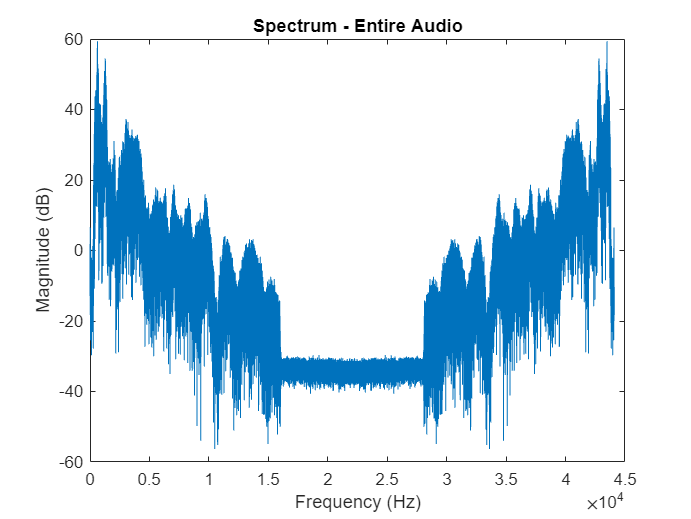

[y, fs] = audioread('C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-3\Opera.wav');

segmentSize = 20000; % Number of samples per segment
numSegments = 11; % Total number of segments

overlap = 0; % No overlap between segments

stepSize = (segmentSize - overlap);
figureCounter = 1;
fullSpectrum = fft(y);
fFull = linspace(0, fs, length(fullSpectrum));

figure(figureCounter);
plot(fFull, 20 * log10(abs(fullSpectrum)));
title('Spectrum - Entire Audio');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

figureCounter = figureCounter + 1; 

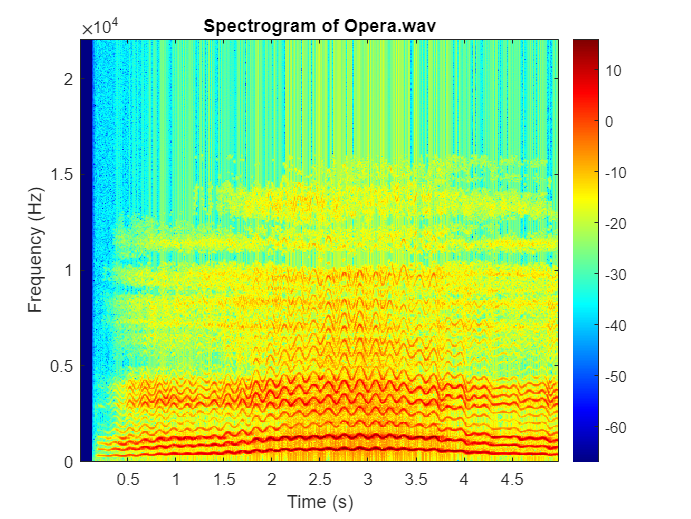

[x, fs] = audioread('C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-3\Opera.wav');

windowSize = 1024;  % Size of the analysis window
overlap = 512;     % Overlap between consecutive windows
nfft = 1024;        % Number of FFT points
[S, F, T] = spectrogram(x, windowSize, overlap, nfft, fs);

S_dB = 10 * log10(abs(S));

figure;
imagesc(T, F, S_dB);  % Display the spectrogram
axis xy;              % Invert the y-axis to have lower frequencies at the bottom
colormap jet;        % Set the colormap (you can choose different colormaps)
colorbar;            % Add a colorbar to the plot
title('Spectrogram of Opera.wav');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

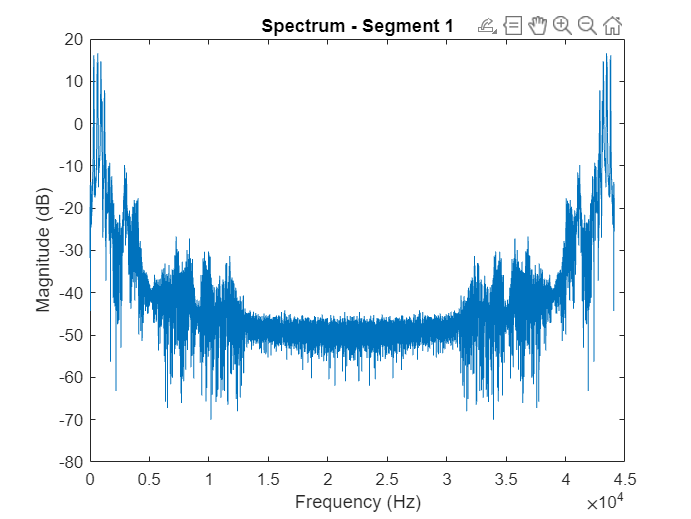

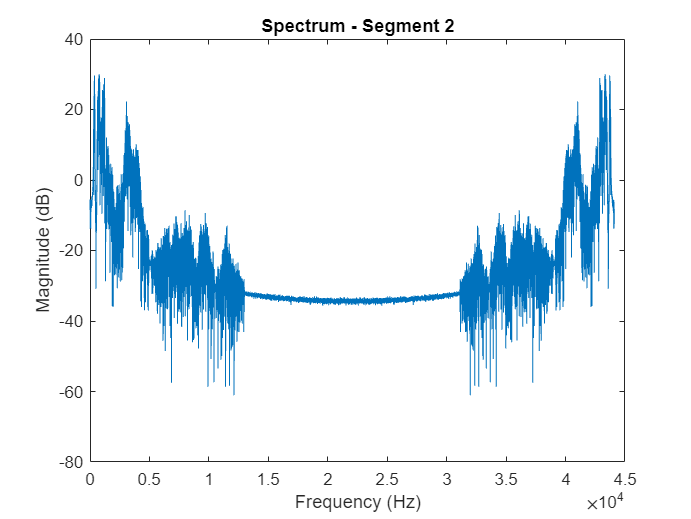

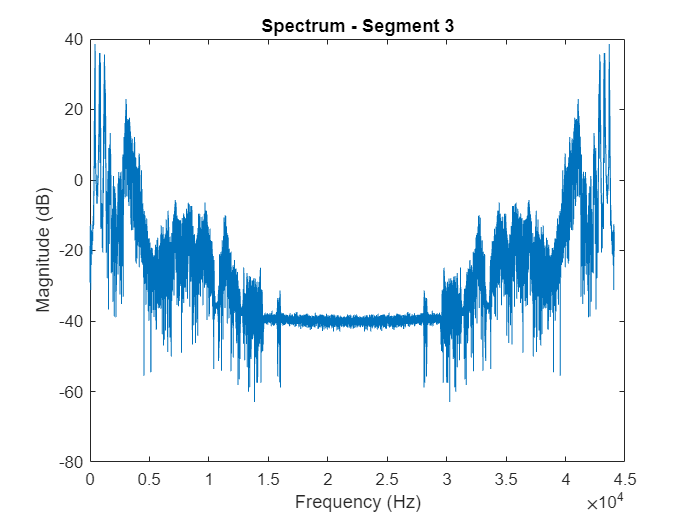

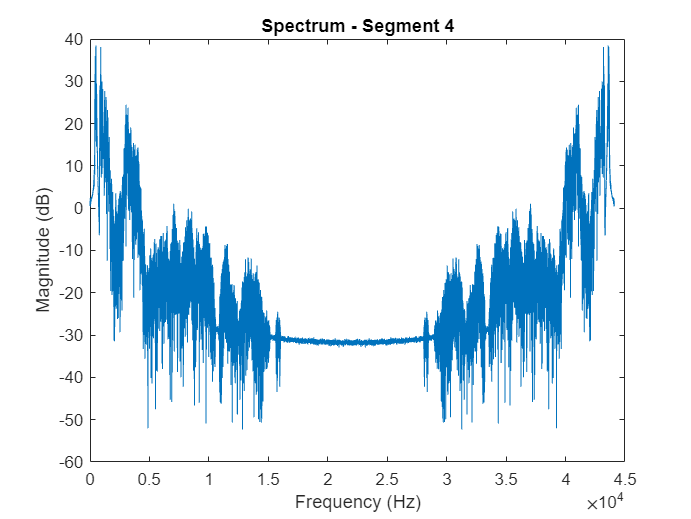

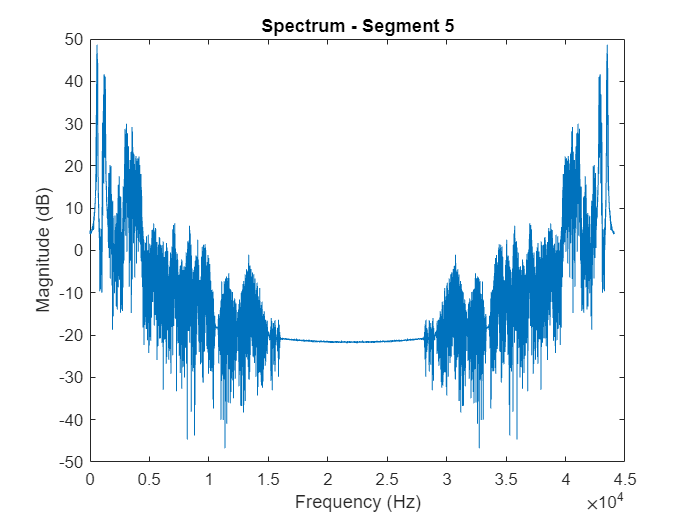

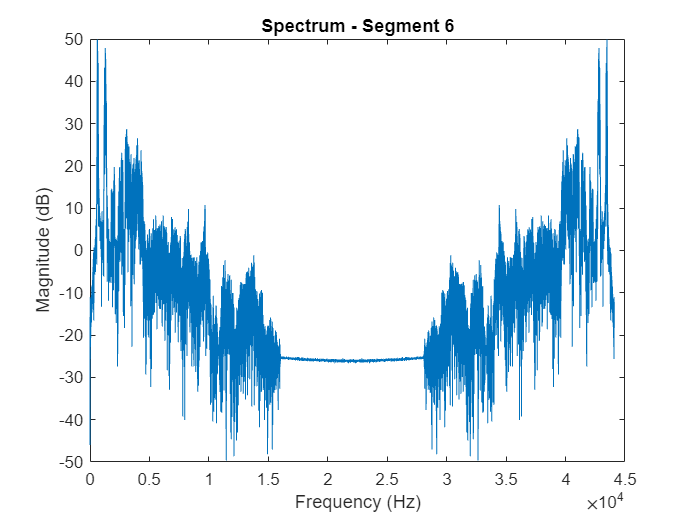

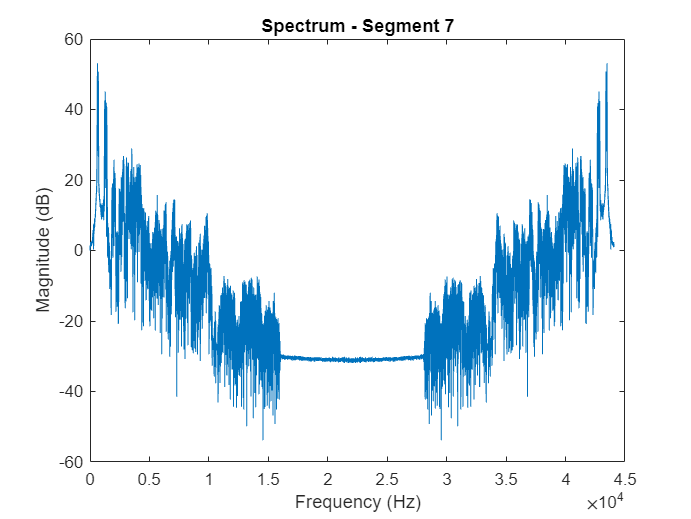

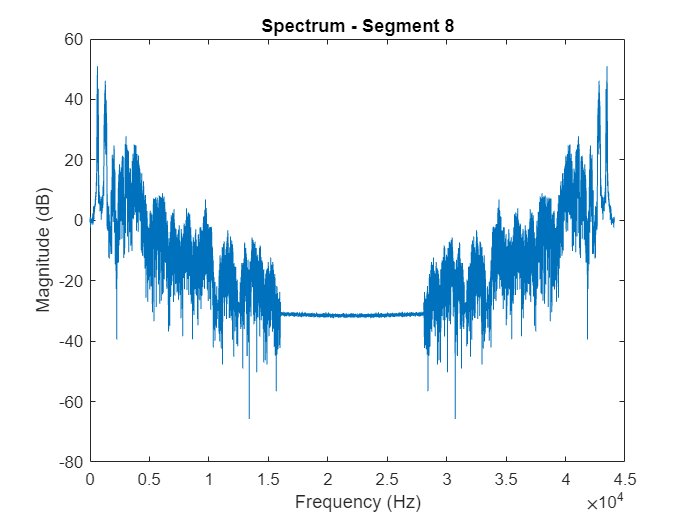

for i = 1:numSegments
    startIdx = (i - 1) * stepSize + 1;
    endIdx = startIdx + segmentSize - 1;

    segment = y(startIdx:endIdx);
    spectrum = fft(segment);
    f = linspace(0, fs, segmentSize);

    figure(figureCounter);
    plot(f, 20 * log10(abs(spectrum)));
    title(['Spectrum - Segment ', num2str(i)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    figureCounter = figureCounter + 1;
end